Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 7**

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DFT function
dft = @(xn, n) xn * exp((-1j * 2*pi/length(n)) .* (n' * (0:(length(n)-1))));

% defining the IDFT function
idft = @(xn, n) xn * exp((1j * 2*pi/length(n)) .* ...
    (n' * (0:(length(n)-1)))) ./ length(n);

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;

Q1:


$$Let\ x_f[n] = x[[-8-n]]_7$$



$$x_f[0] = x[[0-8]]_7 = x[[-8]]_7 = x[6]$$



$$x_f[1] = x[[-1-8]]_7 = x[[-9]]_7 = x[5]$$



$$x_f[2] = x[[-2-8]]_7 = x[[-10]]_7 = x[4]$$



$$x_f[3] = x[[-3-8]]_7 = x[[-11]]_7 = x[3]$$



$$x_f[4] = x[[-4-8]]_7 = x[[-12]]_7 = x[2]$$



$$x_f[5] = x[[-5-8]]_7 = x[[-13]]_7 = x[1]$$



$$x_f[6] = x[[-6-8]]_7 = x[[-14]]_7 = x[0]$$


xn = [1, 2, -3, 4, -5, 0, 0];
n = 0:6;
k = 0:6;

R7n = [1, 1, 1, 1, 1, 1, 1];

% Taking the 7-point DFT of x[n]
Xw = dft(xn, n);

% Introducing a time-shift of -8
N0 = -8;
Xw = Xw .* exp(1j .* 2*pi/length(n) .* k .* N0);

% Taking inverse DFT such that resultant signal is time reversed
xfn = dft(Xw, n) ./ length(n);
% ignoring the imaginary part for clean output
xfn = real(xfn);

% Comparing the original and final sequences
display(xn);

xn =      1     2    -3     4    -5     0     0


display(xfn);

xfn =    -0.0000   -0.0000   -5.0000    4.0000   -3.0000    2.0000    1.0000


% y[n] = x[[-n-8]]7 .* R7[n]
yn = xfn .* R7n;
display(yn);

yn =    -0.0000   -0.0000   -5.0000    4.0000   -3.0000    2.0000    1.0000


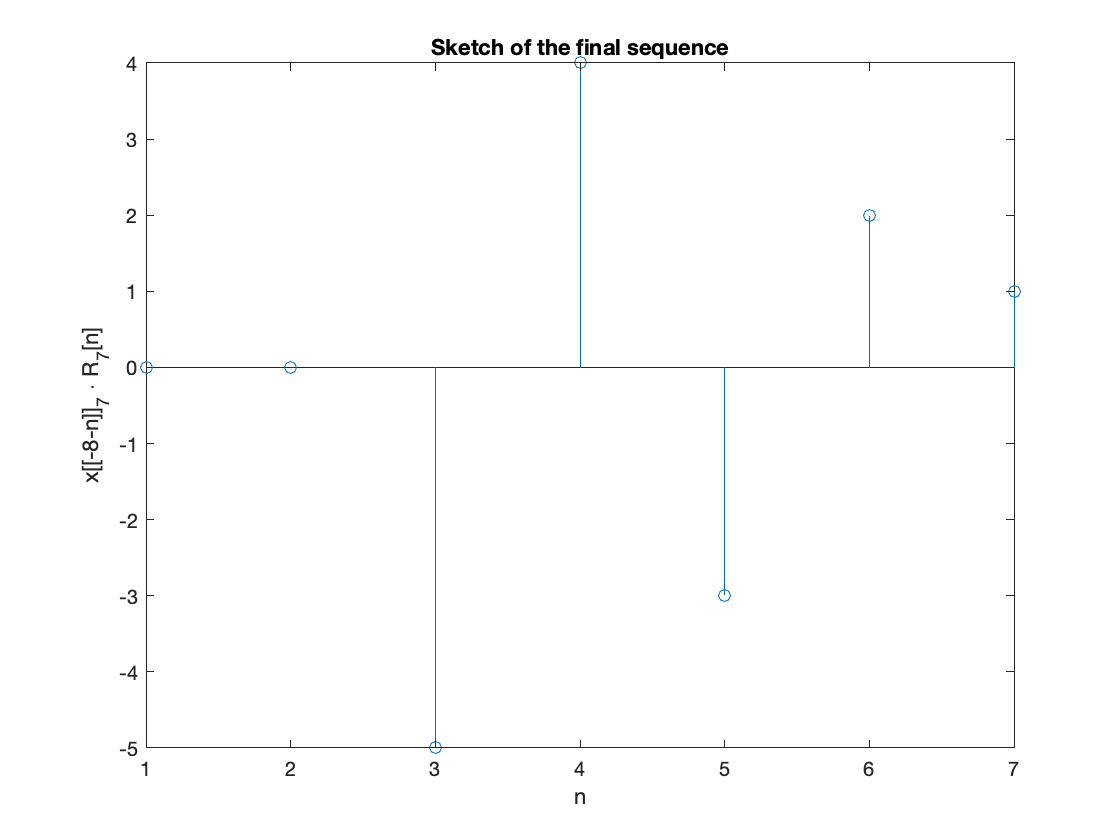

stem(yn); xlabel("n"); ylabel("x[[-8-n]]_7 \cdot R_7[n]");
title("Sketch of the final sequence");

Q2:

x1n = [1, 3, 5, 7, 9, -7, -5, -3, -1];

C = circulnt(x1n, length(x1n));

display(C);

C =      1    -1    -3    -5    -7     9     7     5     3
     3     1    -1    -3    -5    -7     9     7     5
     5     3     1    -1    -3    -5    -7     9     7
     7     5     3     1    -1    -3    -5    -7     9
     9     7     5     3     1    -1    -3    -5    -7
    -7     9     7     5     3     1    -1    -3    -5
    -5    -7     9     7     5     3     1    -1    -3
    -3    -5    -7     9     7     5     3     1    -1
    -1    -3    -5    -7     9     7     5     3     1


The $circulnt$ function has been verified, as is evident from the above result.

Q3:

x1n = [1, 3, 2, -1];
x2n = [2, 1, 0, -1];

% (a) obtaining x3 using convolution
x3n = conv(x1n, x2n);
display(x3n);

x3n =      2     7     7    -1    -4    -2     1


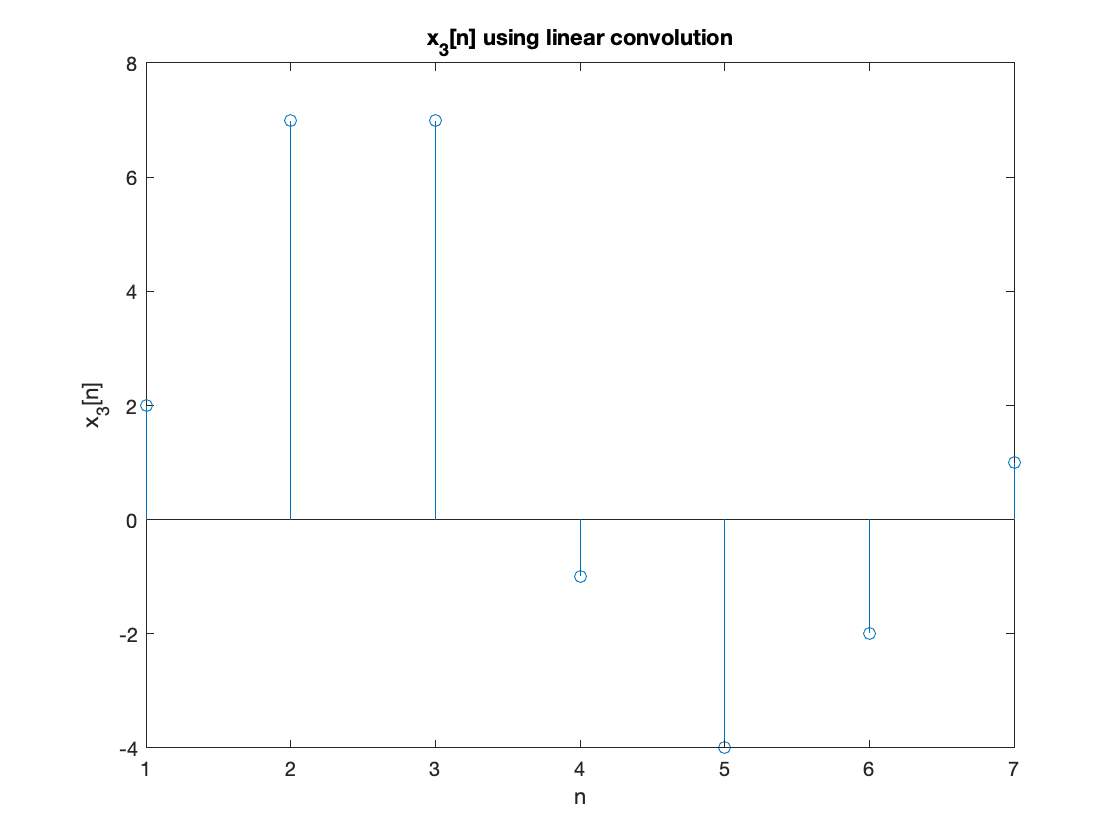

stem(x3n); xlabel("n"); ylabel("x_3[n]");
title("x_3[n] using linear convolution");

% (b)
% obtaining x3n using circular convolution
x2_padded = [x2n zeros(1, length(x1n) - 1)];
x1_padded = [x1n zeros(1, length(x2n) - 1)];
x3n_circ = (circulnt(x1_padded, length(x1_padded)) * x2_padded')';
display(x3n_circ);

x3n_circ =      2     7     7    -1    -4    -2     1


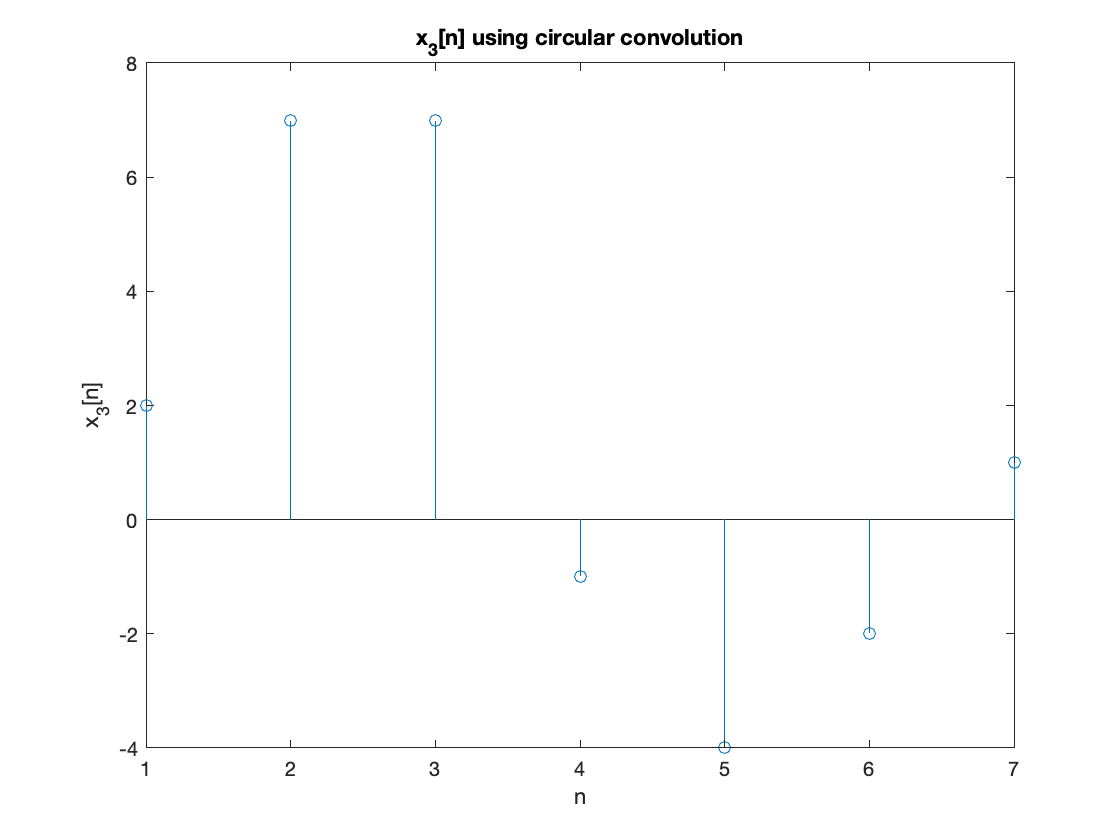

stem(x3n_circ); xlabel("n"); ylabel("x_3[n]");
title("x_3[n] using circular convolution")

% obtaining x4 using circular convolution for verification
C2 = circulnt(x1n, length(x1n));
x4n_circ = (C2 * x2n')';
display(x4n_circ);

x4n_circ =     -2     5     8    -1


% obtaining x4 using linear convolution (from x3)
Identity = eye(length(x1n)); % Identity matrix
M = [Identity Identity(:,1:length(x2n)-1)];
display(M);

M =      1     0     0     0     1     0     0
     0     1     0     0     0     1     0
     0     0     1     0     0     0     1
     0     0     0     1     0     0     0


x4n_lin = (M * x3n')';
display(x4n_lin);

x4n_lin =     -2     5     8    -1


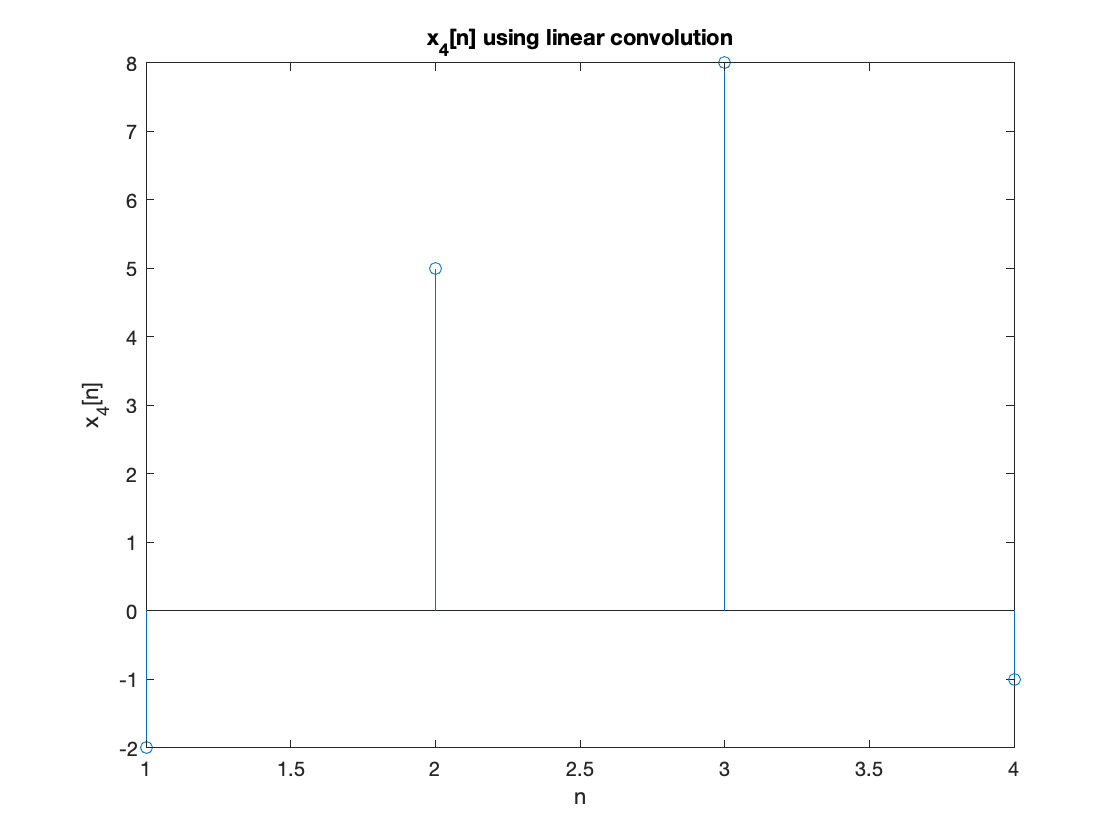

stem(x4n_lin); xlabel("n"); ylabel("x_4[n]");
title("x_4[n] using linear convolution");

Q4:

n = 0:3;

% FFT & DFT
% computing DFT of x1 and x2 using DFT algorithm
X1k_dft = dft(x1n, n);
X2k_dft = dft(x2n, n);

display(X1k_dft');

   5.0000 + 0.0000i
  -1.0000 + 4.0000i
   1.0000 - 0.0000i
  -1.0000 - 4.0000i



display(X2k_dft');

   2.0000 + 0.0000i
   2.0000 + 2.0000i
   2.0000 - 0.0000i
   2.0000 - 2.0000i



% computing DFT of x1 & x2 using FFT, and comparing results
X1k_fft = fft(x1n);
X2k_fft = fft(x2n);

display(X1k_fft');

   5.0000 + 0.0000i
  -1.0000 + 4.0000i
   1.0000 + 0.0000i
  -1.0000 - 4.0000i



display(X2k_fft');

   2.0000 + 0.0000i
   2.0000 + 2.0000i
   2.0000 + 0.0000i
   2.0000 - 2.0000i



We can see from the above results that the DFT and FFT algorithms give identical results.

% IFFT and IDFT
% computing x4 using IDFT
x4n_idft = idft(X1k_dft .* X2k_dft, n);
display(x4n_idft');

  -2.0000 + 0.0000i
   5.0000 + 0.0000i
   8.0000 - 0.0000i
  -1.0000 - 0.0000i



% computing x4 using IFFT
x4n_ifft = ifft(X1k_fft .* X2k_fft);
display(x4n_ifft');

    -2
     5
     8
    -1



We can see from the comparision of $x_4[n]_{idft}$ and $x_4[n]_{ifft}$ that the IDFT and IFFT algorithms produce identical results. Hence, the outcomes of FFT and IFFT have been verified.

These algorithms improve the efficiency of the DFT and IDFT by using the $divide\ and\ conquer$ technique by dividing the transform into two pieces of size $N/2$ at each step, to reduce the computational complexity of DFT from $O(n^2)$ to $O\left(\frac{n}{2}\cdot log(n)\right)$. However, this algorithm is only applicable when $n$ is a power of 2, but this limitation can be overcome by using a different factorisation.

function C = circulnt(x, N)
    extraDigitsRequired = N - length(x);
    x = [x, zeros(1, extraDigitsRequired)];
    C = toeplitz(x, circshift(flip(x), 1));
end